clear; clc; close all;

% === Parametri ===
epochs = 20;
learning_rate = 0.01;

%% Caricamento dataset
fprintf('>>> Caricamento dataset...\n');

>>> Caricamento dataset...


load('dataset/volti_dataset.mat');  % A (m×n), labels...
img_h = 112; img_w = 92; num_classes = max(labels);
imgs = reshape(A, img_h, img_w, []);
labels = labels(:);

%% Split train/test (stesso schema)
train_idx = []; test_idx = [];
for s = 1:num_classes
    idx = find(labels == s);
    idx = idx(randperm(length(idx)));
    train_idx = [train_idx, idx(1:7)];
    test_idx  = [test_idx,  idx(8:end)];
end
imgs_train = imgs(:,:,train_idx); y_train = labels(train_idx)';
imgs_test = imgs(:,:,test_idx); y_test = labels(test_idx)';

% One–hot encoding
num_train = numel(y_train);
Y_train   = zeros(num_classes, num_train);
for j = 1:num_train
    Y_train(y_train(j), j) = 1;
end

%% --- Addestramento ---
fprintf('>>> Training CNN (2 conv layers, no toolbox)...\n');

>>> Training CNN (2 conv layers, no toolbox)...


tic;
[filters1, bias1, filters2, bias2, W_fc, b_fc, loss_hist] = ...
    cnn_two_layers(imgs_train, Y_train, epochs, learning_rate);

[CNN] Epoch 5/20, Loss = 22.2236
[CNN] Epoch 10/20, Loss = 19.3353
[CNN] Epoch 15/20, Loss = 14.6018
[CNN] Epoch 20/20, Loss = 13.3983


fprintf('Fine training in %.2f s\n', toc);

Fine training in 143.95 s



%% --- Test ---
% (Solo forward: conv1, pool1, conv2, pool2, flatten, fc, softmax)
fprintf('>>> Test set evaluation...\n');

>>> Test set evaluation...


num_test = length(y_test);
img_h = size(imgs_test,1); img_w = size(imgs_test,2);

filter_size1 = 5; num_filters1 = 8;
filter_size2 = 3; num_filters2 = 16;
pool_size = 2;

conv1_h = img_h - filter_size1 + 1;   conv1_w = img_w - filter_size1 + 1;
pool1_h = floor(conv1_h/pool_size);   pool1_w = floor(conv1_w/pool_size);
conv2_h = pool1_h - filter_size2 + 1; conv2_w = pool1_w - filter_size2 + 1;
pool2_h = floor(conv2_h/pool_size);   pool2_w = floor(conv2_w/pool_size);

fc_input_size = pool2_h * pool2_w * num_filters2;

correct = 0;
for i = 1:num_test
    x_img = imgs_test(:,:,i);

    % --- FORWARD PASS ---
    % Conv1 + ReLU
    conv1 = zeros(conv1_h, conv1_w, num_filters1);
    for f = 1:num_filters1
        conv1(:,:,f) = conv2(x_img, rot90(filters1(:,:,f),2), 'valid') + bias1(f);
        conv1(:,:,f) = max(0, conv1(:,:,f));
    end
    pool1 = zeros(pool1_h, pool1_w, num_filters1);
    for f = 1:num_filters1
        pool1(:,:,f) = maxpool2d(conv1(:,:,f), pool_size);
    end

    % Conv2 + ReLU
    conv2_out = zeros(conv2_h, conv2_w, num_filters2);
    for f2 = 1:num_filters2
        acc = zeros(conv2_h, conv2_w);
        for f1 = 1:num_filters1
            acc = acc + conv2(pool1(:,:,f1), rot90(filters2(:,:,f2,f1),2), 'valid');
        end
        conv2_out(:,:,f2) = max(0, acc + bias2(f2));
    end
    pool2 = zeros(pool2_h, pool2_w, num_filters2);
    for f = 1:num_filters2
        pool2(:,:,f) = maxpool2d(conv2_out(:,:,f), pool_size);
    end

    % Flatten + FC
    x_fc = reshape(pool2, [], 1);
    z_fc = W_fc * x_fc + b_fc;
    z_fc = z_fc - max(z_fc);
    expz = exp(z_fc);
    y_pred = expz / sum(expz);
    [~, pred_label] = max(y_pred);

    if pred_label == y_test(i)
        correct = correct + 1;
    end
end
acc_cnn = correct / num_test * 100;
fprintf('Accuracy CNN (test set): %.2f%%\n', acc_cnn);

Accuracy CNN (test set): 0.00%


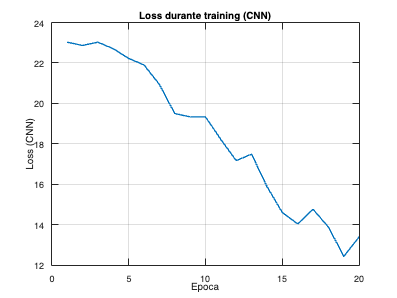


%% --- Plot della loss ---
figure; plot(1:epochs, loss_hist, 'LineWidth',1.5);
xlabel('Epoca'); ylabel('Loss (CNN)');
title('Loss durante training (CNN)');
grid on;

function out = maxpool2d(mat, pool_size)
    s = size(mat);
    out = zeros(floor(s(1)/pool_size), floor(s(2)/pool_size));
    for i = 1:size(out,1)
        for j = 1:size(out,2)
            region = mat( (i-1)*pool_size+1:i*pool_size, (j-1)*pool_size+1:j*pool_size );
            out(i,j) = max(region(:));
        end
    end
end

